AS_wavelengths = [410, 440, 470, 510, 550, 583, 620, 670];
VEML_wavelengths = [650, 550, 450];
b = 10;
t_int = [40, 80, 160, 320, 640, 1280];

R_integration_time = reshape(cell2mat(RED(10,:)),[],6)

R_integration_time = 1.0e+04 *

    0.0040    0.0080    0.0160    0.0319    0.0641    0.1271
    0.0019    0.0038    0.0075    0.0150    0.0297    0.0596
    0.0043    0.0086    0.0172    0.0344    0.0690    0.1371
    0.0072    0.0145    0.0289    0.0579    0.1162    0.2309
    0.0033    0.0065    0.0129    0.0258    0.0514    0.1027
    0.1076    0.2147    0.4285    0.8560    1.7263    3.4066
    0.3466    0.6929    1.3842    2.7682    5.5480    6.5535
    0.0051    0.0103    0.0206    0.0412    0.0824    0.1648
    0.2014    0.4025    0.8039    1.6074    3.2227    6.4091
    0.0247    0.0495    0.0989    0.1980    0.3947    0.7908


R_integration = R_integration_time./R_integration_time(:,6)

R_integration =     0.0315    0.0629    0.1259    0.2510    0.5040    1.0000
    0.0319    0.0637    0.1258    0.2512    0.4984    1.0000
    0.0314    0.0628    0.1255    0.2510    0.5038    1.0000
    0.0312    0.0628    0.1251    0.2507    0.5033    1.0000
    0.0321    0.0633    0.1256    0.2512    0.5007    1.0000
    0.0316    0.0630    0.1258    0.2513    0.5067    1.0000
    0.0529    0.1057    0.2112    0.4224    0.8466    1.0000
    0.0309    0.0625    0.1250    0.2500    0.4997    1.0000
    0.0314    0.0628    0.1254    0.2508    0.5028    1.0000
    0.0312    0.0626    0.1251    0.2503    0.4990    1.0000


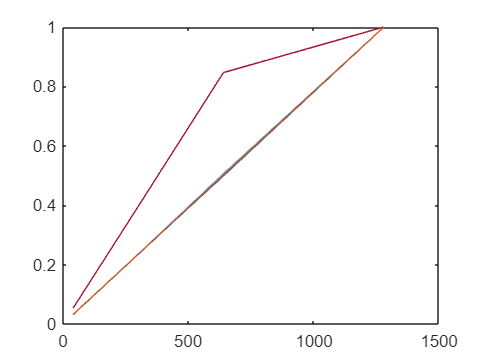


plot(t_int, R_integration(1, :))
hold on
for i = 2:9
    plot(t_int, R_integration(i, :))
end
hold off


R_integration_time = reshape(cell2mat(RED(1,:)),[],6)

R_integration_time = 1.0e+03 *

    0.0030    0.0067    0.0130    0.0250    0.0500    0.0997
    0.0020    0.0030    0.0050    0.0100    0.0200    0.0398
    0.0040    0.0070    0.0140    0.0270    0.0539    0.1070
    0.0056    0.0112    0.0228    0.0447    0.0886    0.1766
    0.0030    0.0050    0.0100    0.0190    0.0375    0.0741
    0.0940    0.1881    0.3770    0.7558    1.5145    3.0264
    0.2660    0.5322    1.0639    2.1281    4.2585    8.4960
    0.0035    0.0077    0.0147    0.0288    0.0576    0.1147
    0.1590    0.3190    0.6370    1.2750    2.5520    5.0938
    0.0170    0.0335    0.0665    0.1323    0.2640    0.5256


R_integration = R_integration_time./R_integration_time(:,6)

R_integration =     0.0301    0.0667    0.1304    0.2508    0.5015    1.0000
    0.0503    0.0755    0.1258    0.2516    0.5031    1.0000
    0.0374    0.0654    0.1308    0.2523    0.5037    1.0000
    0.0317    0.0631    0.1291    0.2531    0.5014    1.0000
    0.0405    0.0675    0.1350    0.2564    0.5061    1.0000
    0.0311    0.0622    0.1246    0.2497    0.5004    1.0000
    0.0313    0.0626    0.1252    0.2505    0.5012    1.0000
    0.0301    0.0676    0.1287    0.2508    0.5028    1.0000
    0.0312    0.0626    0.1251    0.2503    0.5010    1.0000
    0.0323    0.0636    0.1264    0.2517    0.5022    1.0000


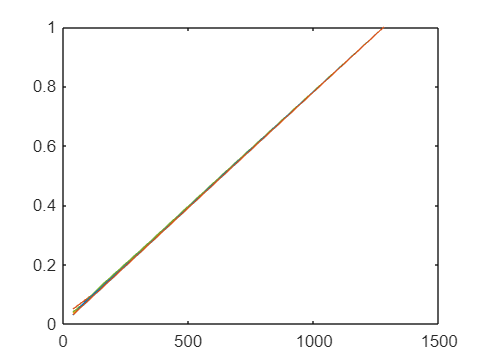


plot(t_int, R_integration(1, :))
hold on
for i = 2:9
    plot(t_int, R_integration(i, :))
end
hold off

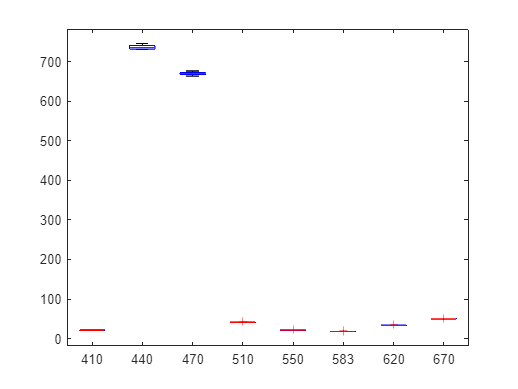

BLUE_Scaled = scale(BLUE);
[BLUE_10_AS, BLUE_10_VEML] = retrieve_int(BLUE_Scaled, b);
boxplot(transpose(BLUE_10_AS(1:8,:)),AS_wavelengths);

% boxplot(transpose(BLUE_10_VEML(1:3,:)),VEML_wavelengths);


RED_Scaled = scale(RED);
[RED_10_AS, RED_10_VEML] = retrieve_int(RED_Scaled, b);
% boxplot(transpose(RED_10_AS(1:8,:)),AS_wavelengths);
% boxplot(transpose(RED_10_VEML(1:3,:)),VEML_wavelengths);


GREEN_Scaled = scale(GREEN);
[GREEN_10_AS, GREEN_10_VEML] = retrieve_int(GREEN_Scaled, b);
% boxplot(transpose(GREEN_10_AS(1:8,:)),AS_wavelengths);
% boxplot(transpose(GREEN_10_VEML(1:3,:)),VEML_wavelengths);

WHITE_Scaled = scale(WHITE);
[WHITE_10_AS, WHITE_10_VEML] = retrieve_int(WHITE_Scaled, b);
% boxplot(transpose(WHITE_10_AS(1:8,:)),AS_wavelengths);
% boxplot(transpose(WHITE_10_VEML(1:3,:)),VEML_wavelengths);

% Brightness vs counts plots for specific integration time
int = dictionary([40, 80, 160, 320, 640, 1280],1:6);
integration_time = 160;
angle = deg2rad(85.5:-4.5:45)

angle =     1.4923    1.4137    1.3352    1.2566    1.1781    1.0996    1.0210    0.9425    0.8639    0.7854


brightness = 100./tan(angle)

brightness =     7.8702   15.8384   24.0079   32.4920   41.4214   50.9525   61.2801   72.6543   85.4081  100.0000


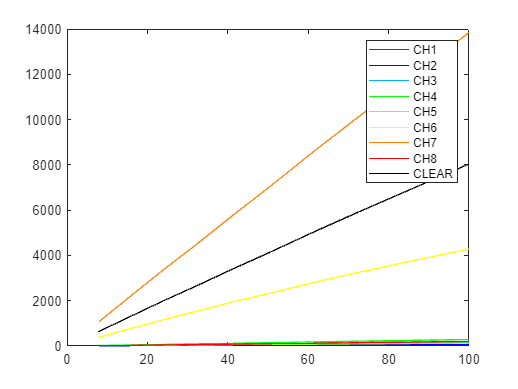


[RED_Brightness_160_AS, RED_Brightness_160_VEML] = retrieve_brightness(RED_Scaled, int(integration_time));
plot(brightness, RED_Brightness_160_AS);
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
ax = gca;
ax.ColorOrder = AS_Colours;

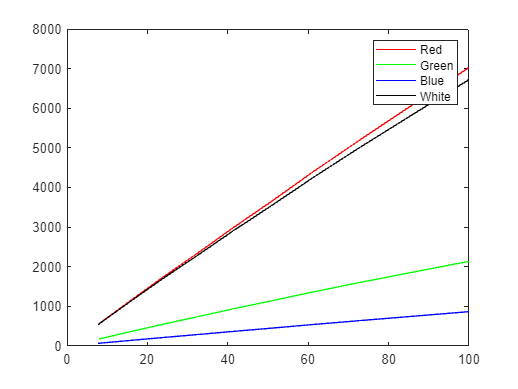


plot(brightness, RED_Brightness_160_VEML);
legend("Red", "Green", "Blue", "White")
ax = gca;
ax.ColorOrder = VEML_Colours;

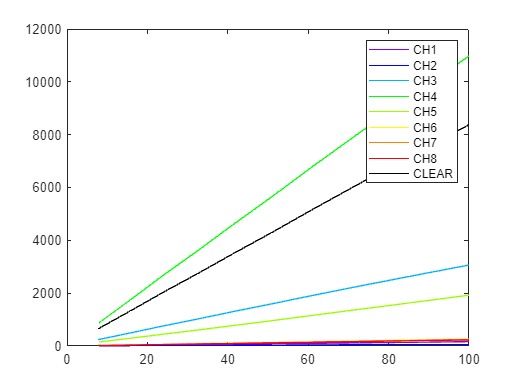



[GREEN_Brightness_160_AS, GREEN_Brightness_160_VEML] = retrieve_brightness(GREEN_Scaled, int(integration_time));
plot(brightness, GREEN_Brightness_160_AS);
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
ax = gca;
ax.ColorOrder = AS_Colours;

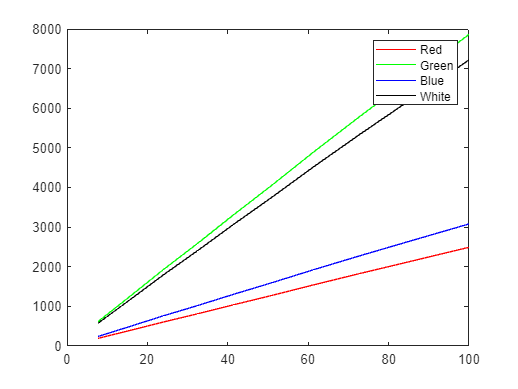


plot(brightness, GREEN_Brightness_160_VEML);
legend("Red", "Green", "Blue", "White")
ax = gca;
ax.ColorOrder = VEML_Colours;

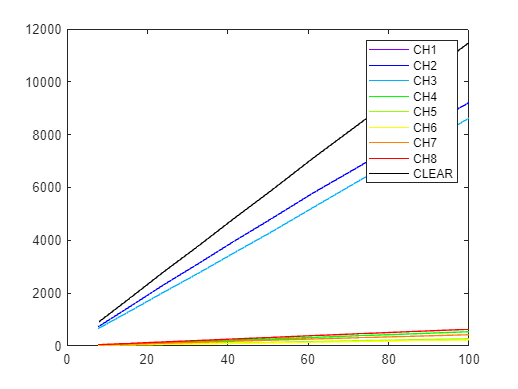



[BLUE_Brightness_160_AS, BLUE_Brightness_160_VEML] = retrieve_brightness(BLUE_Scaled, int(integration_time));
plot(brightness, BLUE_Brightness_160_AS);
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
ax = gca;
ax.ColorOrder = AS_Colours;

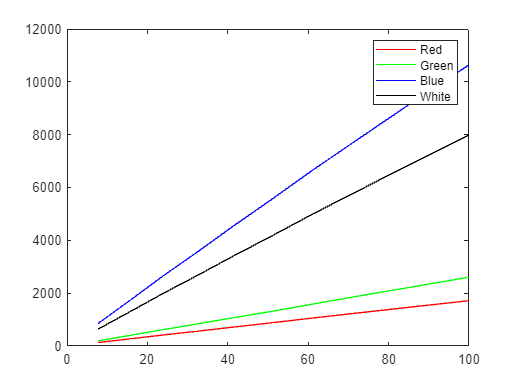


plot(brightness, BLUE_Brightness_160_VEML);
legend("Red", "Green", "Blue", "White")
ax = gca;
ax.ColorOrder = VEML_Colours;

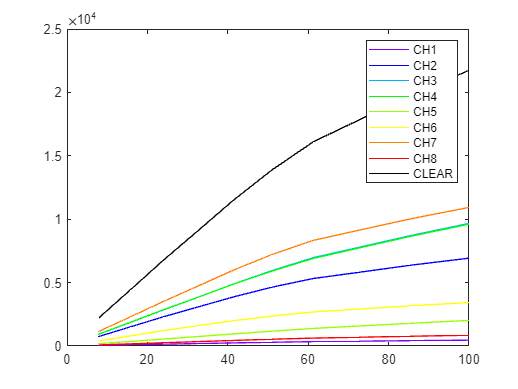



[WHITE_Brightness_160_AS, WHITE_Brightness_160_VEML] = retrieve_brightness(WHITE_Scaled, int(integration_time));
plot(brightness, WHITE_Brightness_160_AS);
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
ax = gca;
ax.ColorOrder = AS_Colours;

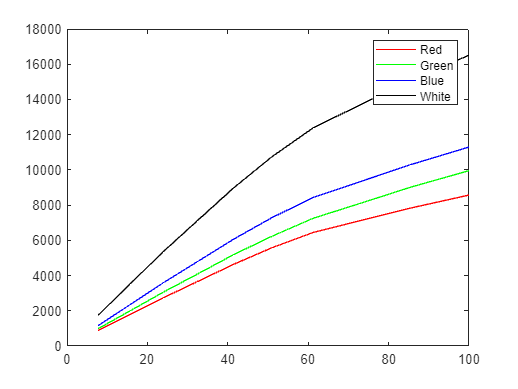


plot(brightness, WHITE_Brightness_160_VEML);
legend("Red", "Green", "Blue", "White")
ax = gca;
ax.ColorOrder = VEML_Colours;

% Normalised Brightness
WHITE_160 = cell2mat(WHITE(:,3));
WHITE_Normalised = WHITE_160./WHITE_160(10,:)

WHITE_Normalised =     0.1021    0.1077    0.0961    0.0970    0.0892    0.1135    0.1047    0.0983    0.1014    0.0968    0.1045    0.1004    0.1042    0.1075    1.0000
    0.2042    0.2190    0.1929    0.1957    0.1779    0.2341    0.2111    0.1978    0.2047    0.1920    0.2103    0.2022    0.2098    0.2152    1.0000
    0.3109    0.3328    0.2944    0.2981    0.2725    0.3546    0.3218    0.3026    0.3117    0.2945    0.3199    0.3077    0.3184    0.3251    1.0000
    0.4184    0.4433    0.3960    0.3994    0.3681    0.4678    0.4313    0.4064    0.4172    0.4003    0.4274    0.4109    0.4246    0.4317    1.0000
    0.5322    0.5590    0.5059    0.5077    0.4732    0.5825    0.5475    0.5182    0.5292    0.5157    0.5409    0.5207    0.5366    0.5433    1.0000
    0.6416    0.6694    0.6146    0.6145    0.5792    0.6898    0.6598    0.6287    0.6384    0.6296    0.6506    0.6256    0.6449    0.6506    1.0000
    0.7452    0.7690    0.7205    0.7187    0.6876    0.7832    0.7624    0

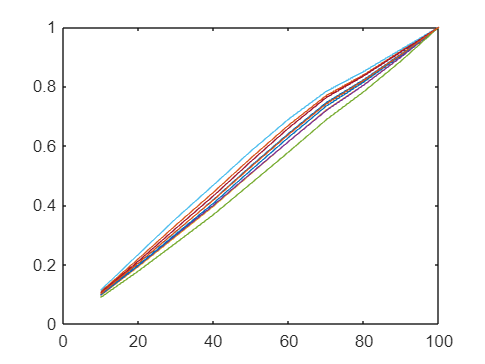

RED_160 = cell2mat(RED(:,3));
RED_Normalised = RED_160./RED_160(10,:);
GREEN_160 = cell2mat(GREEN(:,3));
GREEN_Normalised = GREEN_160./GREEN_160(10,:);
BLUE_160 = cell2mat(BLUE(:,3));
BLUE_Normalised = BLUE_160./BLUE_160(10,:);

brightness = 10:10:100;
brightnessmatrix = repmat(brightness',9);
plot(brightnessmatrix(1:10,1:9), WHITE_Normalised(:,1:9))

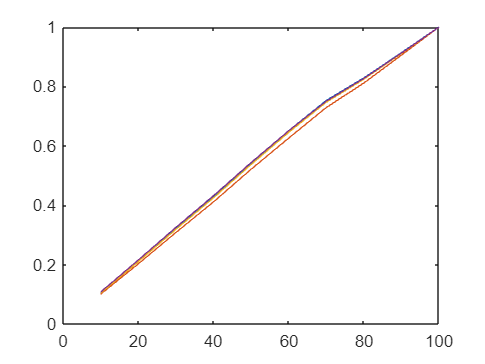


plot(brightnessmatrix(1:10,1:4), WHITE_Normalised(:,11:14))

% Red input, normalised to red channel, t = 160ms, at 100% brightness
RED_160_100 = RED_160(10,:);
RED_AS_Normalise = (RED_160_100(1:8)./32)./(RED_160_100(7)/32)

RED_AS_Normalise =     0.0116    0.0054    0.0124    0.0209    0.0093    0.3095    1.0000    0.0149


RED_VEML_Normalise = RED_160_100(11:13)./RED_160_100(11)

RED_VEML_Normalise =     1.0000    0.3038    0.1233



% Green input, normalised to GREEN channel, t = 160ms, at 100% brightness
GREEN_160_100 = GREEN_160(10,:);
GREEN_AS_Normalise = (GREEN_160_100(1:8)./32)./(GREEN_160_100(4)/32)

GREEN_AS_Normalise =     0.0150    0.0061    0.2792    1.0000    0.1752    0.0239    0.0225    0.0209


GREEN_VEML_Normalise = GREEN_160_100(11:13)./GREEN_160_100(12)

GREEN_VEML_Normalise =     0.3168    1.0000    0.3917



% Blue input, normalised to BLUE channel, t = 160ms, at 100% brightness
BLUE_160_100 = BLUE_160(10,:);
BLUE_AS_Normalise = (BLUE_160_100(1:8)./32)./(BLUE_160_100(2)/32)

BLUE_AS_Normalise =     0.0293    1.0000    0.9362    0.0587    0.0298    0.0251    0.0462    0.0688


BLUE_VEML_Normalise = BLUE_160_100(11:13)./BLUE_160_100(13)

BLUE_VEML_Normalise =     0.1611    0.2447    1.0000


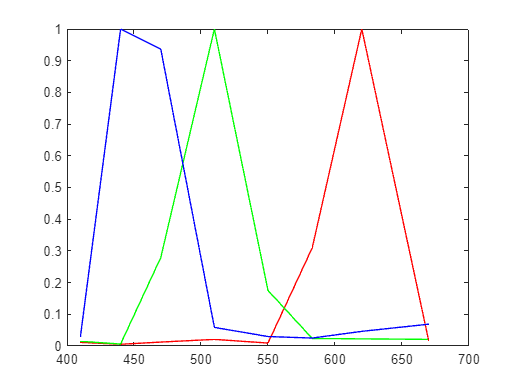


plot(AS_wavelengths,RED_AS_Normalise,'red')
hold on
plot(AS_wavelengths,GREEN_AS_Normalise,'green')
plot(AS_wavelengths,BLUE_AS_Normalise,'blue')
hold off

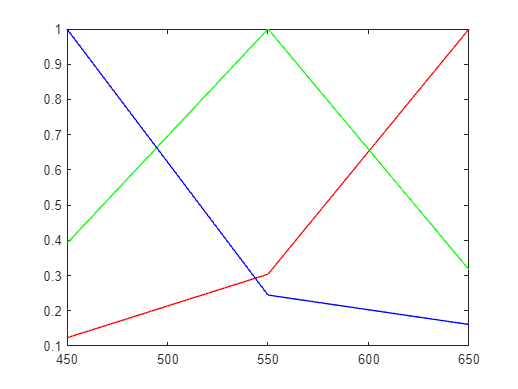


plot(VEML_wavelengths,RED_VEML_Normalise,'red')
hold on
plot(VEML_wavelengths,GREEN_VEML_Normalise,'green')
plot(VEML_wavelengths,BLUE_VEML_Normalise,'blue')
hold off

% SINGLE LED, DIVIDED BY INTEGRATION TIME (NORMALISE)
t = [40, 80, 160, 320, 640, 1280];
RED_SINGLE_AS_N = reshape(cell2mat(RED_SINGLE_AS(1,:)),15,6);
RED_SINGLE_AS_N = RED_SINGLE_AS_N(1:9,:)./t;

RED_SINGLE_VEML_N = reshape(cell2mat(RED_SINGLE_AS(1,:)),15,6);
RED_SINGLE_VEML_N = RED_SINGLE_VEML_N(11:14,:)./t;


GREEN_SINGLE_AS_N = reshape(cell2mat(GREEN_SINGLE_AS(1,:)),15,6);
GREEN_SINGLE_AS_N = GREEN_SINGLE_AS_N(1:9,:)./t;

GREEN_SINGLE_AS_N =          0         0         0         0         0         0
         0         0         0         0         0         0
         0    0.0100    0.0063    0.0041    0.0044    0.0039
    0.0475    0.0563    0.0563    0.0531    0.0516    0.0515
    0.0250    0.0250    0.0250    0.0250    0.0250    0.0242
         0         0         0    0.0016    0.0016    0.0008
         0         0         0         0         0         0
         0         0         0         0         0         0
    0.0500    0.0500    0.0563    0.0531    0.0516    0.0516



GREEN_SINGLE_VEML_N = reshape(cell2mat(GREEN_SINGLE_AS(1,:)),15,6);
GREEN_SINGLE_VEML_N = GREEN_SINGLE_VEML_N(11:14,:)./t;


BLUE_SINGLE_AS_N = reshape(cell2mat(BLUE_SINGLE_AS(1,:)),15,6);
BLUE_SINGLE_AS_N = BLUE_SINGLE_AS_N(1:9,:)./t;

BLUE_SINGLE_VEML_N = reshape(cell2mat(BLUE_SINGLE_AS(1,:)),15,6);
BLUE_SINGLE_VEML_N = BLUE_SINGLE_VEML_N(11:14,:)./t;

WHITE_SINGLE_AS_N = reshape(cell2mat(WHITE_SINGLE_AS(1,:)),15,6);
WHITE_SINGLE_AS_N = WHITE_SINGLE_AS_N(1:9,:)./t;

WHITE_SINGLE_VEML_N = reshape(cell2mat(WHITE_SINGLE_AS(1,:)),15,6);
WHITE_SINGLE_VEML_N = WHITE_SINGLE_VEML_N(11:14,:)./t;

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(10,6);
    for j = 1:10
        for i = 1:6
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

function [COLOUR_BRIGHTNESS_AS, COLOUR_BRIGHTNESS_VEML] = retrieve_int(COLOUR_Scaled, brightness)
    COLOUR_BRIGHTNESS_AS = zeros(9,6);
    COLOUR_BRIGHTNESS_VEML = zeros(4,6);
    for j = 1:9
        for i = 1:6
            COLOUR_BRIGHTNESS_AS(j,i) = COLOUR_Scaled{brightness/10,i}(1,j);
        end
    end
    for j = 1:4
        for i = 1:6
            COLOUR_BRIGHTNESS_VEML(j,i) = COLOUR_Scaled{brightness/10,i}(1,j+10);
        end
    end
end

function [COLOUR_BRIGHTNESS_AS, COLOUR_BRIGHTNESS_VEML] = retrieve_brightness(COLOUR_Scaled, integration_time)
    COLOUR_BRIGHTNESS_AS = zeros(9,10);
    COLOUR_BRIGHTNESS_VEML = zeros(4,10);
    for j = 1:9
        for i = 1:10
            COLOUR_BRIGHTNESS_AS(j,i) = COLOUR_Scaled{i, integration_time}(1,j);
        end
    end
    for j = 1:4
        for i = 1:10
            COLOUR_BRIGHTNESS_VEML(j,i) = COLOUR_Scaled{i, integration_time}(1,j+10);
        end
    end
end
